%% First Order Response
clc; clear variables;

s1 = load("lab3_order1_3.mat");

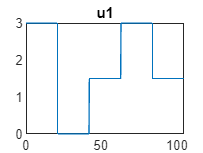


plot(s1.t,s1.data.InputData); title(s1.data.InputName);

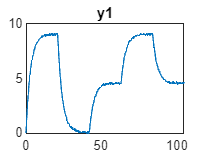

plot(s1.t,s1.data.OutputData); title(s1.data.OutputName);


id = struct("u",s1.data.InputData(1:100),"y",s1.data.OutputData(1:100),"t",s1.t(1:100));
val = struct("u",s1.data.InputData(201:500),"y",s1.data.OutputData(201:500),"t",s1.t(201:500));

y_ss = 1/11*sum(id.y(90:100,:))

y_ss = 8.9910

u_ss = 1/11*sum(id.u(90:100,:))

u_ss = 3

y0 = 0;
u0 = 0;

k = (y_ss-y0)/(u_ss-u0)

k = 2.9970

hs = tf(k,[63*y_ss/100 1])

hs =
 
     2.997
  -----------
  5.664 s + 1
 
Continuous-time transfer function.




y_id_cap = lsim(hs,id.u,id.t);
y_val_cap = lsim(hs,val.u,val.t);

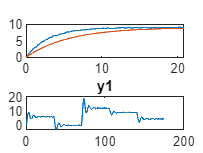


mse_id = 1/100*(id.y)*sum((y_id_cap-id.y).^2);
mse_val = 1/300*(val.y)*sum((y_val_cap-val.y).^2);

figure,
subplot(2,1,1);
plot(id.t,id.y,id.t,y_id_cap); % title("Identification MSE = " + string(mse_id))
subplot(2,1,2);
plot(val.t,val.y,val.t,y_val_cap); % title("Validation MSE = " + string(mse_val))

%% Second Order Response
clear variables;

s2 = load("lab3_order2_3.mat");

plot(s2.t,s2.data.InputData); title(s2.data.InputName);
plot(s2.t,s2.data.OutputData); title(s2.data.OutputName);


id = struct("u",s2.data.InputData(1:100),"y",s2.data.OutputData(1:100),"t",s2.t(1:100));
val = struct("u",s2.data.InputData(201:500),"y",s2.data.OutputData(201:500),"t",s2.t(201:500));

y_ss = 1/11*sum(id.y(90:100,:));
u_ss = 1/11*sum(id.u(90:100,:));
y0 = 0;
u0 = 0;

y_max = max(id.y)

y_max = 9.0748

y_min = min(id.y)

y_min = -0.1688

y1 = 9.07

y1 = 9.0700

y2 = 4.36

y2 = 4.3600

y3 = 7.01

y3 = 7.0100

t1 = 3.5

t1 = 3.5000

t3 = 10.15

t3 = 10.1500


k = (y_ss-y0)/(u_ss-u0) % gain

k = 2.9789

M = (y1-y_ss)/(y_ss-y0)

M = 0.5224

M1 = (y_ss-y2)/(y1-y_ss)

M1 = 0.5134

zeta = log(1/M1)/(sqrt(pi^2+log(M1)^2)) % damping factor

zeta = 0.2076

wn = abs((2*pi)/((t3-t1)*sqrt(1-zeta^2)))% natural frequency

wn = 0.9659

wn1 = 2/(t3-t1)*sqrt(pi^2+(log(M1))^2)

wn1 = 0.9659

hs = tf(k*wn^2,[1 2*zeta*wn wn^2])

hs =
 
          2.779
  ----------------------
  s^2 + 0.401 s + 0.9329
 
Continuous-time transfer function.




y_id_cap = lsim(hs,id.u,id.t);
y_val_cap = lsim(hs,val.u,val.t);

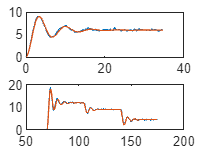


mse_id = 1/100*(id.y)*sum((y_id_cap-id.y).^2);
mse_val = 1/300*(val.y)*sum((y_val_cap-val.y).^2);

figure,
subplot(2,1,1);
plot(id.t,id.y,id.t,y_id_cap); % title("Identification MSE = " + string(mse_id))
subplot(2,1,2);
plot(val.t,val.y,val.t,y_val_cap); % title("Validation MSE = " + string(mse_val))